% channel_awgn.m
clear; clc;
load('tx_data.mat','tx_sig');   % loads tx_sig

SNR_dB = 15;    % try 15 dB (you can vary 5->25)
rx_sig = awgn(tx_sig, SNR_dB, 'measured');

save('rx_data.mat','rx_sig','SNR_dB');
fprintf('Channel: added AWGN at %d dB\n', SNR_dB);

Channel: added AWGN at 15 dB


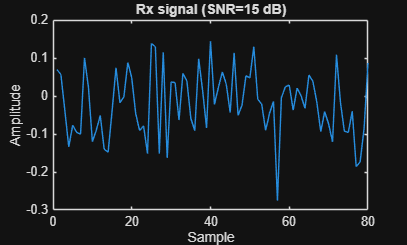


figure; plot(real(rx_sig));
title(['Rx signal (SNR=' num2str(SNR_dB) ' dB)']); xlabel('Sample'); ylabel('Amplitude');
% after plotting in channel_awgn.m
saveas(gcf,'rx_time.png');